# *Drosophila* Body dynamics

clear; close all; clc

Body Inertia

I_b = 5.2e-13; % Body Interia [N*m*s^2]
% I_b = 5.9e-13; % Body Interia [N*m*s^2] +- 3.3e-14

Body Damping

C_b = 5.2e-13; % Body Damping [N*m*s]
% C_b = 1.1e-12; % Body Damping [N*m*s] +- 2.3e-11

Time Constant

tau = I_b/C_b; % time constant

Body Plant

G = tf(1,[tau 1])


G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



Delay Simulations

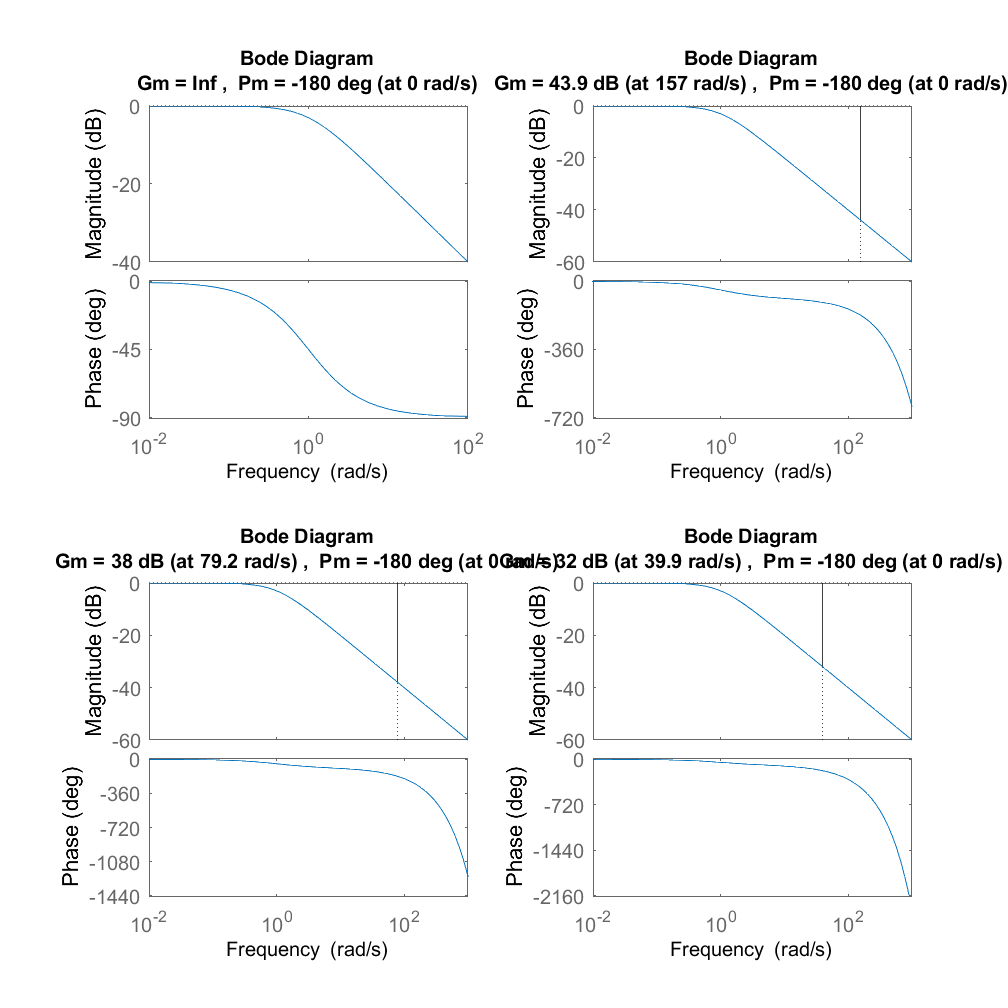

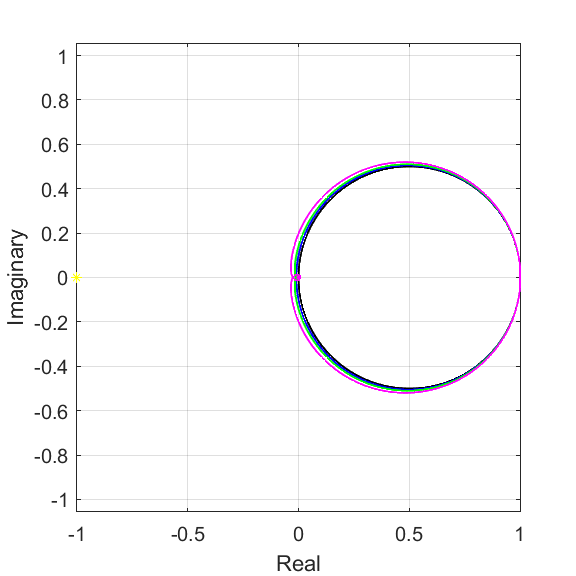

delay = [0 10 20 40]*10^(-3);
freq = linspace(0,1000,500000)';

fig(1) = figure (1) ; clf
fig(2) = figure (2) ; clf
fig(3) = figure (3) ; clf
set(fig,'Color','w','Units','inches')

fig(1).Position = [2 2 5 5];
fig(2).Position = [2 2 7 7];
fig(3).Position = [2 2 4 4];

CC = {'k','b','g','m','c'};
for kk = 1:length(delay)
    G.OutputDelay = delay(kk);
    
    [mag,phase,wout] = bode(G,2*pi*freq);
    mag = squeeze(mag);
    phase = squeeze(phase);
    wout = squeeze(wout)./(2*pi);
    
    [Gm,Pm,Wcg,Wcp] = margin(G);
    % Gm = 20*log10(Gm);
    Wcg = Wcg/(2*pi);
    Wcp = Wcp/(2*pi);
    Gm = 1/Gm;
    
    figure (1)
    ax(1) = subplot(2,1,1) ; hold on
    plot(wout,mag,'-','Color',[0.5 0.5 0.5],'LineWidth',1)
%     plot(Wcg,Gm/100,'*','Color',CC{kk})
    
    ax(2) = subplot(2,1,2) ; hold on
    plot(wout,phase,'-','Color',CC{kk},'LineWidth',1)
    plot(Wcg,-180,'o','Color','k','MarkerSize',5)
    text(Wcg,-200,[num2str(Wcg) 'Hz'])
    
    figure (2)
    subplot(ceil(length(delay)/2),2,kk)
    margin(G)
    
    figure (3)
%     nyquist(G) ; hold on
    [re,im] = nyquist(G,[-flipud(freq) ; freq]) ; hold on
    plot(squeeze(re),squeeze(im),'Color',CC{kk},'LineWidth',1)
    plot(-1,0,'*y','MarkerSize',5)
    xlabel('Real')
    ylabel('Imaginary')
    box on
    grid on
    axis square
    axis equal
end

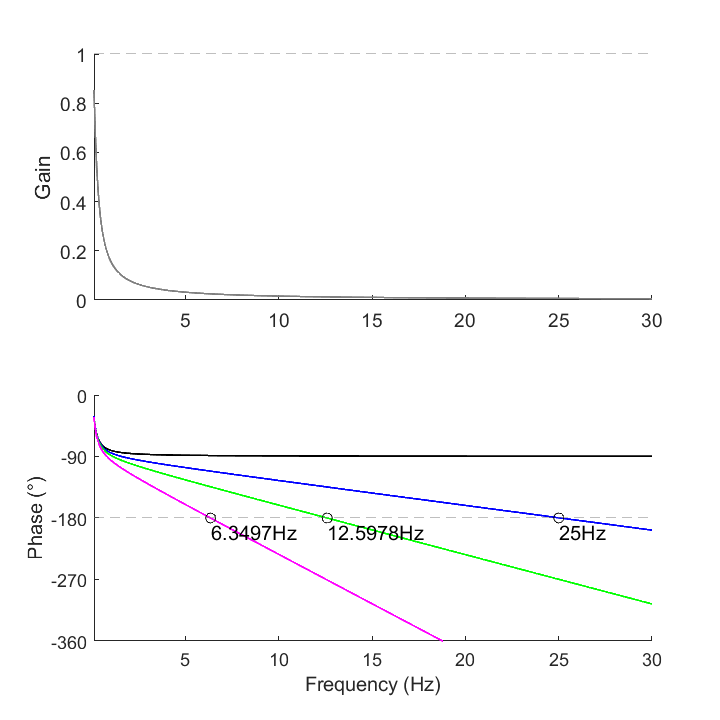

axes(ax(2)) ; hold on
plot([0 100],[-180 -180],'--','Color',[0.5 0.5 0.5])
linkaxes(ax,'x')
ax(1).YLabel.String = 'Gain';
ax(2).YLabel.String = ['Phase (' char(176) ')'];
ax(2).XLabel.String = 'Frequency (Hz)';
ax(2).YLim = [-(360*1) 0];
ax(2).YTick = (-360*5):90:90;
set(ax,'XLim',[0.1 30])
% set(ax,'XScale','log')

axes(ax(1)) ; hold on
plot(freq,1*ones(length(freq),1),'--','Color',[0.5 0.5 0.5])

axes(ax(2)) ; hold on
plot(freq,-180*ones(length(freq),1),'--','Color',[0.5 0.5 0.5])

% fig(2).Visible = 'on';

# *Drosophila* Body dynamics with head

clearvars -except HeadFree tf1 tf2 tf3 tf4 tf 5 tf6 chirp_tf tf7 tf8
close all; clc

Body Inertia

% I = 5.2e-13; % Body Interia [N*m*s^2]
I_b = 5.9e-13; % Body Interia [N*m*s^2] +- 3.3e-14

Body Damping

% C = 5.2e-13; % Body Damping [N*m*s]
C_b = 1.1e-12; % Body Damping [N*m*s] +- 2.3e-11

Time Constant

tau = I_b/C_b; % time constant

Body Plant

G = tf(1,[tau 1]);
G.IODelay = 40e-3


G =
 
                      1
  exp(-0.04*s) * ------------
                 0.5364 s + 1
 
Continuous-time transfer function.



Reference to Error

R2E = tf(tf8)


R2E =
 
  From input "u1" to output "y1":
                    83.75 s^2 + 1330 s + 1.342e04
  exp(-0.01*s) * -----------------------------------
                 s^3 + 114.2 s^2 + 2999 s + 1.182e04
 
Name: tf8
Continuous-time transfer function.



% R2E.IODelay = 10e-3

Reference to Body

R2B = R2E*G


R2B =
 
  From input to output "y1":
                             83.75 s^2 + 1330 s + 1.342e04
  exp(-0.05*s) * -----------------------------------------------------
                 0.5364 s^4 + 62.28 s^3 + 1723 s^2 + 9337 s + 1.182e04
 
Continuous-time transfer function.



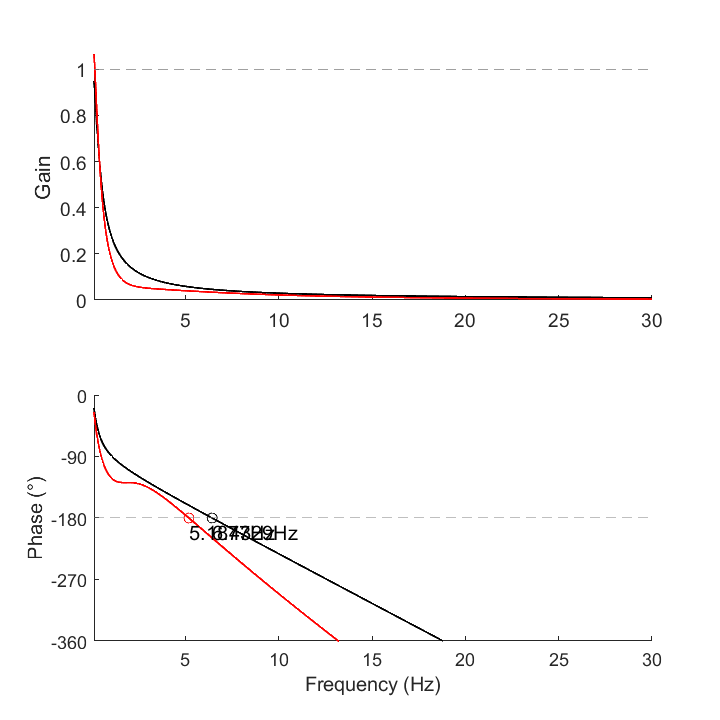

fig(1) = figure (1); clf
fig(1).Units = 'inches';
fig(1).Position = [2 2 5 5];
fig(1).Color = 'w';
hold on
freq = linspace(0,1000,500000)';

[mag,phase,wout] = bode(G,2*pi*freq);
mag = squeeze(mag);
phase = squeeze(phase);
wout = squeeze(wout)./(2*pi);

[Gm,Pm,Wcg,Wcp] = margin(G);
Wcg = Wcg/(2*pi);
Wcp = Wcp/(2*pi);
Gm = 1/Gm;
    
ax(1) = subplot(2,1,1) ; hold on
    plot(wout,mag,'-','Color','k','LineWidth',1)

ax(2) = subplot(2,1,2) ; hold on
    plot(wout,phase,'-','Color','k','LineWidth',1)
    plot(Wcg,-180,'o','Color','k','MarkerSize',5)
    text(Wcg,-200,[num2str(Wcg) 'Hz'])

[mag,phase,wout] = bode(R2B,2*pi*freq);
mag = squeeze(mag);
phase = squeeze(phase);
wout = squeeze(wout)./(2*pi);

[Gm,Pm,Wcg,Wcp] = margin(R2B);
Wcg = Wcg/(2*pi);
Wcp = Wcp/(2*pi);
Gm = 1/Gm;
    
ax(1) = subplot(2,1,1) ; hold on
    plot(wout,mag,'-','Color','r','LineWidth',1)

ax(2) = subplot(2,1,2) ; hold on
    plot(wout,phase,'-','Color','r','LineWidth',1)
    plot(Wcg,-180,'o','Color','r','MarkerSize',5)
    text(Wcg,-200,[num2str(Wcg) 'Hz'])
        
axes(ax(2)) ; hold on
plot([0 100],[-180 -180],'--','Color',[0.5 0.5 0.5])
linkaxes(ax,'x')
ax(1).YLabel.String = 'Gain';
ax(2).YLabel.String = ['Phase (' char(176) ')'];
ax(2).XLabel.String = 'Frequency (Hz)';
ax(2).YLim = [-(360*1) 0];
ax(2).YTick = (-360*5):90:90;
set(ax,'XLim',[0.1 30])
% set(ax,'XScale','log')

axes(ax(1)) ; hold on
plot(freq,1*ones(length(freq),1),'--','Color',[0.5 0.5 0.5])

axes(ax(2)) ; hold on
plot(freq,-180*ones(length(freq),1),'--','Color',[0.5 0.5 0.5])